% Load the train data and tuned model
filename='airline_train.csv';
df = readtable(filename,'VariableNamingRule','preserve');
df

df = 103594×24 table
    Var1    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ____    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________    __________________________    ________________________    ____________

      0       0             1          13           0   

% Delete the first columns as it is not necesarry
df = removevars(df,{'Var1'});
df

df = 103594×23 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________    __________________________    ________________________    ____________

      0             1          13           0             1            4


% Divide dependent variable and independent variable
% Also, as can be seen from correlation matrix, arrivial and departure
% delayed in minutes are removed as this is not interestingly correlated
% with satisfaction
% Dataset used for prediction was choosen for 5000 samples for
% computational reasons
y = df(1:5000,23)

y = 5000×1 table
    satisfaction
    ____________

         0      
         0      
         1      
         0      
         1      
         0      
         0      
         1      
         0      
         0      
         0      
         0      
         0      
         1      
         0      
         0      


X = df(1:5000,1:20)

X = 5000×20 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness
    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________

      0             1          13           0             1            460                    3                              4                              3                     1                5                  3        


% Implement Random_Forest
% Load the train data
filename='airline_train.csv';
df = readtable(filename,'VariableNamingRule','preserve');
df

df = 103594×24 table
    Var1    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ____    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________    __________________________    ________________________    ____________

      0       0             1          13           0   


% Delete the first columns as it is not necesarry
df = removevars(df,{'Var1'});
df

df = 103594×23 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________    __________________________    ________________________    ____________

      0             1          13           0             1            4


% Divide dependent variable and independent variable
% Also, as can be seen from correlation matrix, arrivial and departure
% delayed in minutes are removed as this is not interestingly correlated
% with satisfaction
% Dataset used for prediction was choosen for 5000 samples for
% computational reasons
y = df(1:5000,23)

y = 5000×1 table
    satisfaction
    ____________

         0      
         0      
         1      
         0      
         1      
         0      
         0      
         1      
         0      
         0      
         0      
         0      
         0      
         1      
         0      
         0      


X = df(1:5000,1:20)

X = 5000×20 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness
    ______    _____________    ___    ______________    _____    _______________    _____________________    _________________________________    ______________________    _____________    ______________    _______________    ____________    ______________________    ________________    ________________    ________________    _______________    ________________    ___________

      0             1          13           0             1            460                    3                              4                              3                     1                5                  3        


% Implement Random_Forest
% Reproducible allows to duplicate the same result
tree = templateTree('Reproducible',true,'type','classification','Surrogate','off','NumVariablesToSample',9,'MaxNumSplits',292)

tree = 近似テンプレート classification Tree.

        SplitCriterion: []
             MinParent: []
               MinLeaf: []
             MaxSplits: 292
          NVarToSample: 9
           MergeLeaves: []
                 Prune: []
        PruneCriterion: []
               QEToler: []
            NSurrogate: 'off'
                MaxCat: []
                AlgCat: []
    PredictorSelection: []
          UseChisqTest: []
                Stream: []
          Reproducible: 1
               Version: 2
                Method: 'Tree'
                  Type: 'classification'


Mdl_RF = fitcensemble(X,y.satisfaction,'Method','bag','Learners', ...
    'tree');

% Create 10 Fold cross-validation
CVMdl = crossval(Mdl_RF,'Kfold',10);
mdlLoss = kfoldLoss(CVMdl)

mdlLoss = 0.0566


% Predict the model
[~,posterior] = kfoldPredict(CVMdl)

posterior =     0.9900    0.0100
    0.9600    0.0400
    0.0200    0.9800
    0.9500    0.0500
    0.0800    0.9200
    1.0000         0
    1.0000         0
         0    1.0000
    0.9267    0.0733
    1.0000         0



% Dependent variable contains binary classification 
CVMdl.ClassNames

ans =      0
     1



% Calcurate false positive rate and true positive rate
[fpr,tpr,~,auc] = perfcurve(y.satisfaction,posterior(:,2),CVMdl.ClassNames(2));
auc

auc = 0.9852

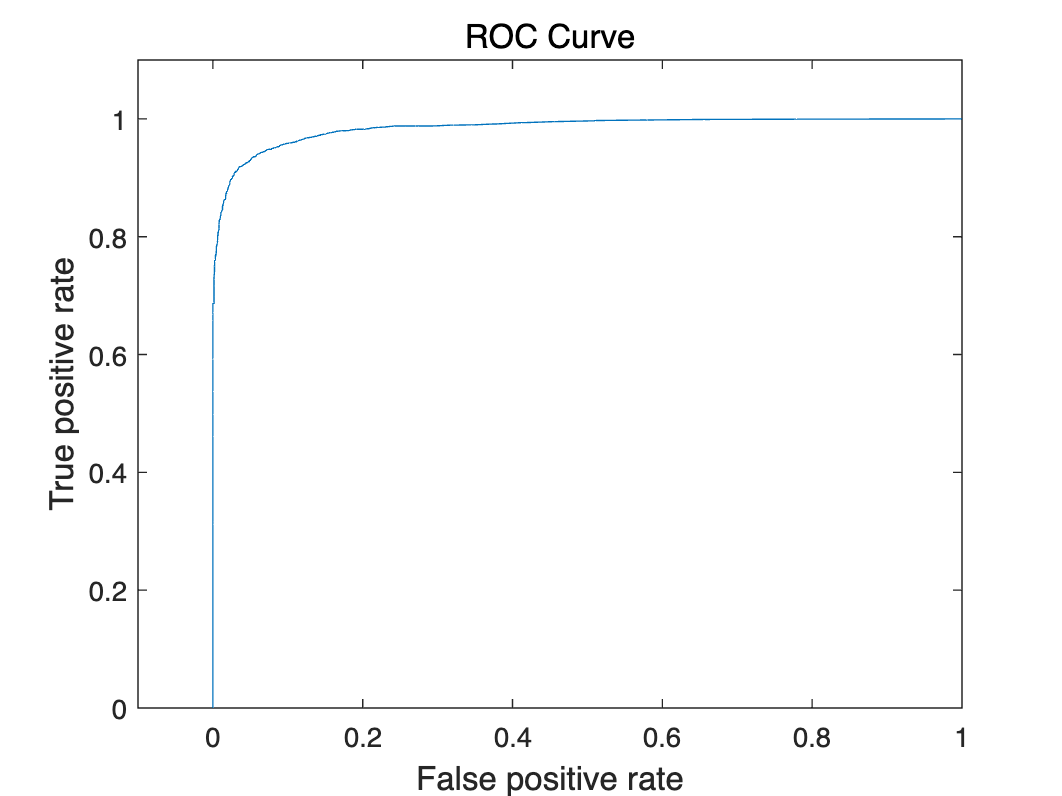


% Visualise ROC Courve
figure;
plot(fpr,tpr)
h = gca;
h.XLim(1) = -0.1;
h.YLim(2) = 1.1;
xlabel('False positive rate','FontSize',12)
ylabel('True positive rate','FontSize',12)
title('ROC Curve','FontSize',12)


% Show confusion matrix for validation set
predPos = kfoldPredict(CVMdl)

predPos =      0
     0
     1
     0
     1
     0
     0
     1
     0
     0


Confusion_Matrix = confusionmat(y.satisfaction,predPos);
Confusion_Matrix

Confusion_Matrix =         2716         107
         176        2001



% Visualise heatmap for correaltion matrix
h = heatmap(Confusion_Matrix)

h =   HeatmapChart のプロパティ:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  すべてのプロパティ を表示


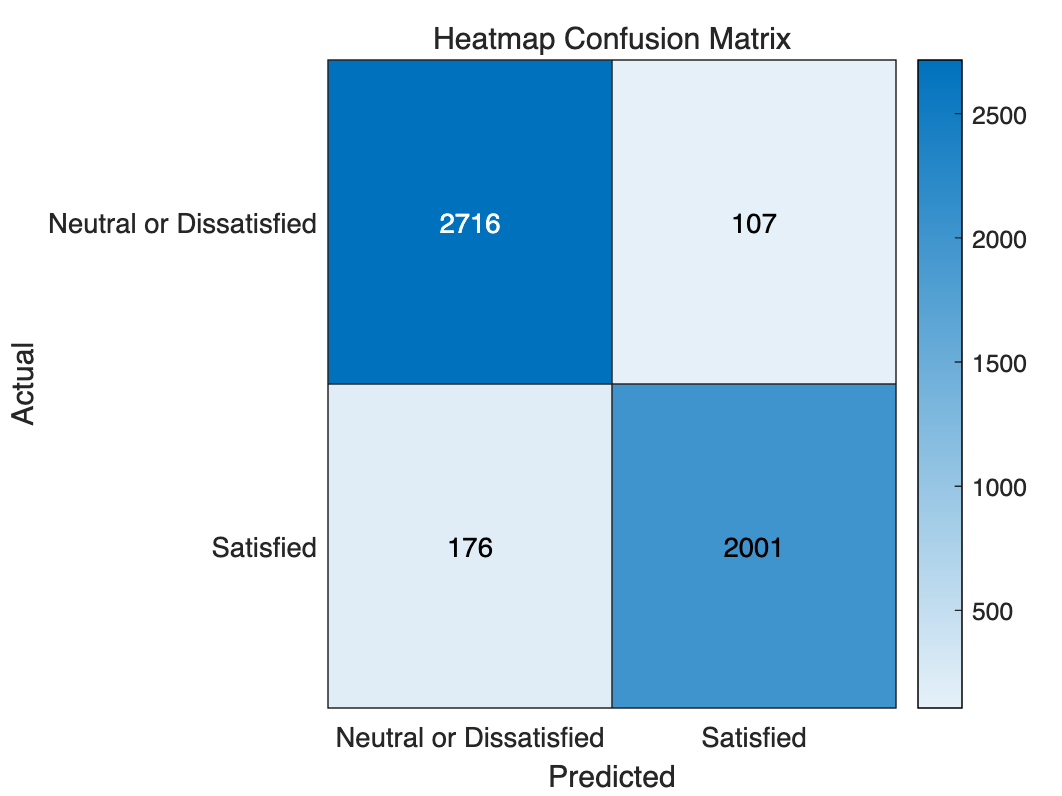

h.Title = 'Heatmap Confusion Matrix';
h.XLabel = 'Predicted';
h.YLabel = 'Actual';
h.XDisplayLabels = {'Neutral or Dissatisfied','Satisfied'};
h.YDisplayLabels = {'Neutral or Dissatisfied','Satisfied'};


% Show the accuracy
Accuracy = trace(Confusion_Matrix)/sum(Confusion_Matrix, 'all')

Accuracy = 0.9434


% Calcurate precision and recall
diagonal = diag(Confusion_Matrix)

diagonal =         2716
        2001


sum_rows = sum(Confusion_Matrix, 2)

sum_rows =         2823
        2177



precision = diagonal ./ sum_rows

precision =     0.9621
    0.9192


mean_precision = mean(precision)

mean_precision = 0.9406


sum_columns = sum(Confusion_Matrix, 1)

sum_columns =         2892        2108



recall = diagonal ./ sum_columns'

recall =     0.9391
    0.9492


mean_recall = mean(recall)

mean_recall = 0.9442



% Calcurate F1 score based upon precision and recall
F1_score = 2*((mean_precision*mean_recall)/(mean_precision+mean_recall))

F1_score = 0.9424

% Save the model
save('Random_Forest_Train_With_HPtuning','Mdl_RF');